# Transformación Invariante de Maddern

## ¿Qué es?

La transformación invariante de Maddern es un método que genera imágenes invariantes a cambios en la iluminación, reduciendo la influencia de sombras y variaciones en la intensidad de la luz. Se basa en un modelo de espectro del sensor de la cámara y la luz incidente.

## Funcionamiento básico de la transformación

**1. Relación entre canales de color:**

Dada una cámara con sensibilidad espectral $F(\lambda) $, el modelo de respuesta de un canal específico $R$ a la luz de una longitud de onda particular $\lambda$ se define como:


$$R^{x,E} = a^x \cdot n^x \cdot I^x \int S^x(\lambda) E(\lambda) F(\lambda) d\lambda$$


donde:

- $a^x$� y $n^x$: vectores que representan la dirección de la luz y la normal de la superficie.

- $I^x$�: intensidad de la luz en el punto $x$.

- $S^x(\lambda)$: reflectancia espectral de la superficie.

- $E(\lambda)$: espectro de la fuente de luz.

**2. Espacio logarítmico-cromático:**

Se transforman las relaciones de los canales de color al espacio logarítmico-cromático tomando el logaritmo de la respuesta espectral:


$$\log(R^{x,E}) = \log (G^x I^x) + \log S^x (\lambda_i) + \log E^x (\lambda_i)$$


donde:

- $G^x=a^x \cdot n^x$ representa la geometría entre la luz y la escena.

**3. Proyección invariante:**

Se proyectan las respuestas espectrales en una dirección específica que elimina el componente de iluminación. La proyección final en la dirección $\alpha$ se realiza utilizando:


$$I = \log (R_2) - \alpha \log (R_1) - (1 - \alpha) \log (R_3)
$$


donde:

- $R_1, R_2, R_3$�: respuestas espectrales de tres canales de color (e.g. $R, G, B$).

- $\alpha$: parámetro determinado por las sensibilidades espectrales de los canales.

**4. Cálculo del parámetro **$\alpha$**:**

El parámetro $\alpha$ se calcula para garantizar que la proyección sea independiente de la temperatura de color $T$ de la luz:


$$\frac{1}{\lambda_2} = \frac{\alpha}{\lambda_1} + \frac{1 - \alpha}{\lambda_3}$$


**5. Transformación invariante de Maddern:**

Finalmente, se aplica la siguiente transformación para obtener una imagen invariante:


$$I_{Maddern} = 0.5 + \log(G) - \alpha \log(B) - (1 - \alpha) \log(R)$$


## Análisis de la implementación:

**1. Parámetros de entrada:**

- $RGB$: imagen en formato RGB.

- $alpha$: parámetro para aproximación logarítmica.

**2. Separación de los canales:**

Primero, la función guarda por separado cada canal de la imagen, $R$, $G$ y $B$.

R = double(RGB(:,:,1));
G = double(RGB(:,:,2));
B = double(RGB(:,:,3));

**3. Calculo del parámetro **$\alpha$

El parámetro $\alpha

$ se cancula en una función a parte y se pasa como parámetro.

alpha = (lambda3 / (lambda3 - lambda1)) * (1/lambda2 - 1/lambda3);

**4. Transformación invariante:**

Finalmente, la función realiza la transformación invariante con parámetro $\alpha$:

I_Maddern = 0.5 + log(G) - alpha*log(B) - (1 - alpha)*log(R);

### Código completo

function alpha = calcular_alpha(lambda1, lambda2, lambda3)
    alpha = (lambda3 / (lambda3 - lambda1)) * (1/lambda2 - 1/lambda3);
end

function I_Maddern = maddern_transform(RGB, alpha)
    %Separación de la imagen RGB por canales en double
    R = double(RGB(:,:,1));
    G = double(RGB(:,:,2));
    B = double(RGB(:,:,3));
    
    % Transformación invariante
    I_Maddern = 0.5 + log(G) - alpha*log(B) - (1 - alpha)*log(R);
end

Un ejemplo de una imagen del programa y su correspondiente transformación:

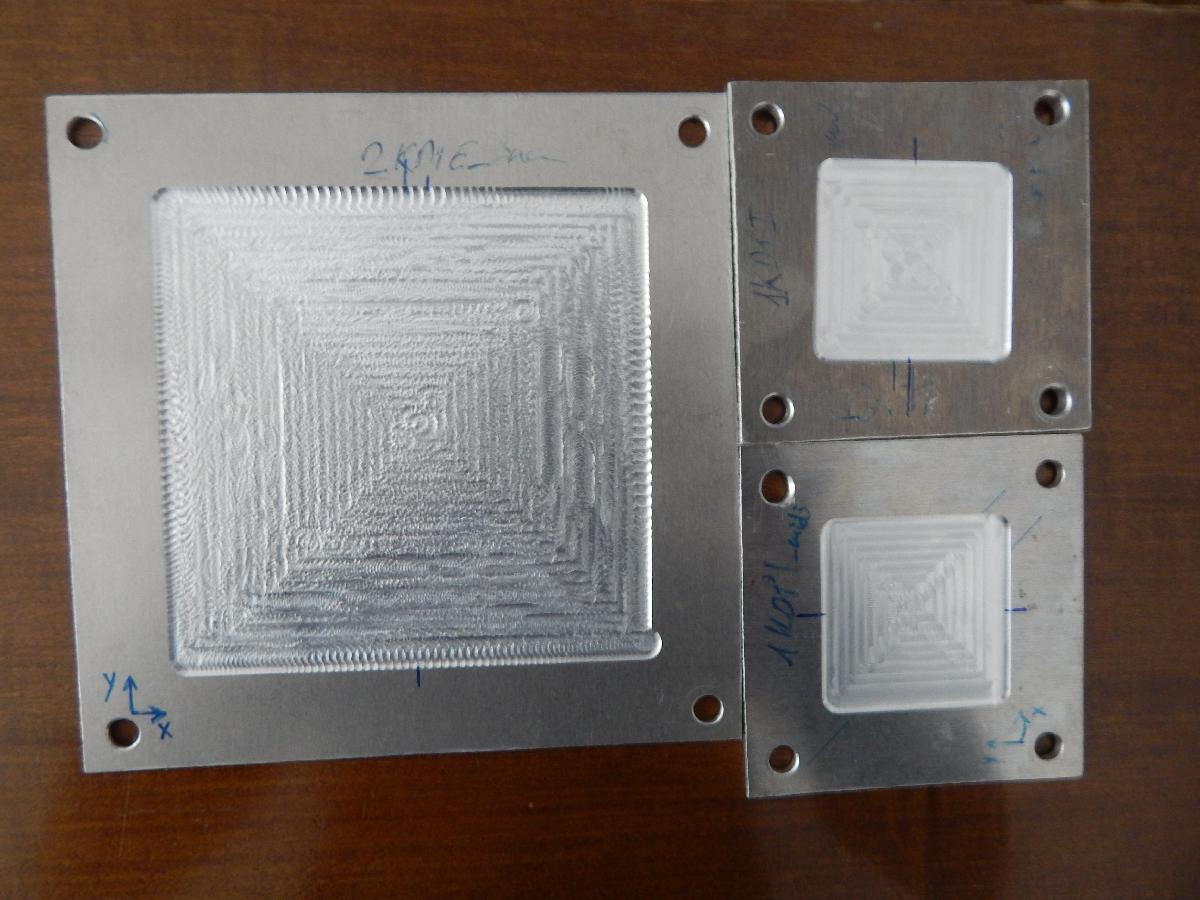    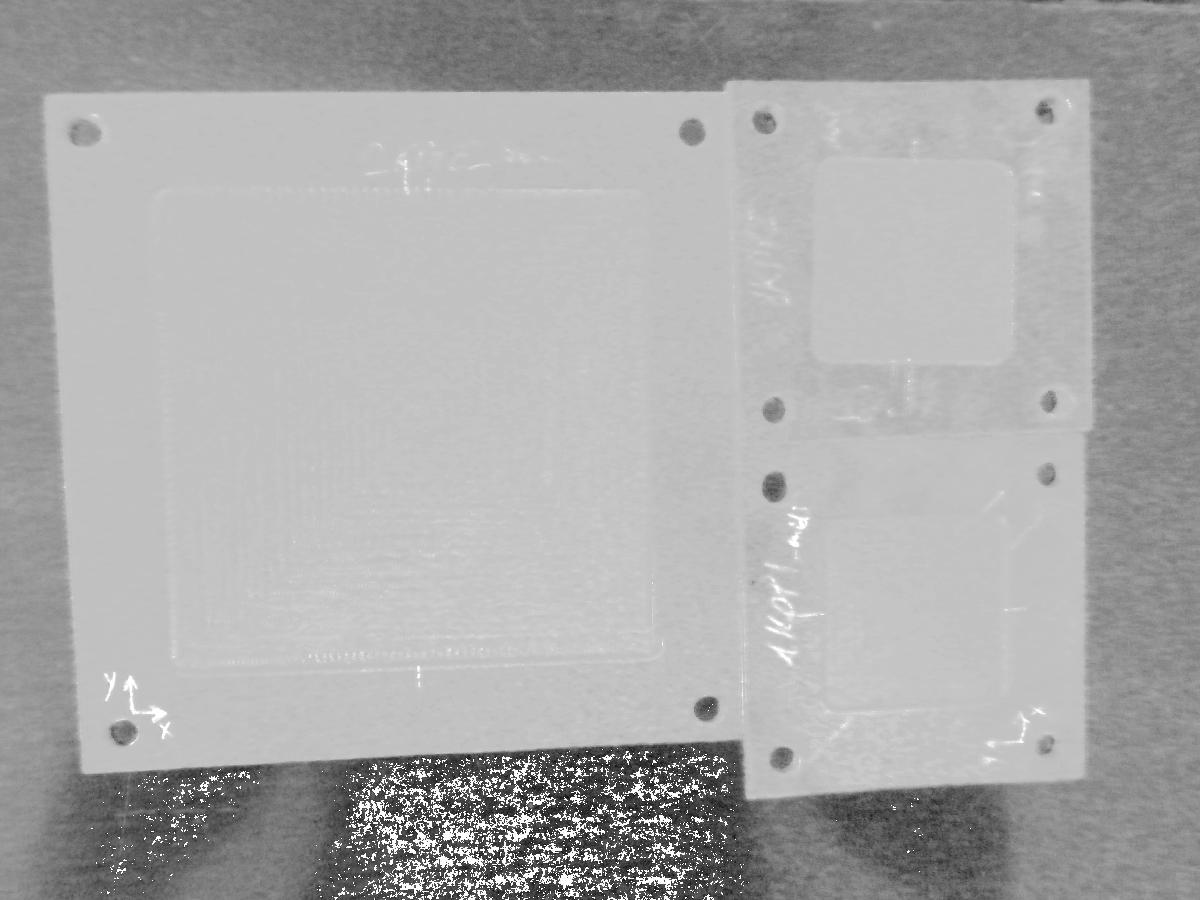

## Referencias

- Maddern, W., Stewart, A. D., McManus, C., Upcroft, B., Churchill, W., & Newman, P. "Illumination invariant imaging: Applications in robust vision-based localisation, mapping and classification for autonomous vehicles," IEEE Intelligent Transportation Systems (ITSC), pp. 328-335, 2014.